# ELEC-8103 – Modelling, Estimation, and Dynamic Systems

# Assignment 4

# Deadline: **5.11.2023 at 23:59**

# **Problem 1 (5 points)**

- **The goal of this task is to analyze the following dynamic system:**

## 
$$G\left(s\right)=\frac{1}{s^2 +3s+2}$$


## **a)**

- Create a transfer function model $G\left(s\right)$. **Hint: **Use [**tf**](https://se.mathworks.com/help/control/ref/tf.html).

- Generate a pseudorandom binary signal input with a sample rate of 10 Hz and with a duration of 200 seconds. **Hint**: Use [**idinput**](https://se.mathworks.com/help/ident/ref/idinput.html).

- Simulate the system’s response to the generated input signal. **Hint:** Use [**lsim**](https://se.mathworks.com/help/ident/ref/dynamicsystem.lsim.html).

- Create a figure and plot both the input and output signals of the model on two subplots.

**(1 point)**

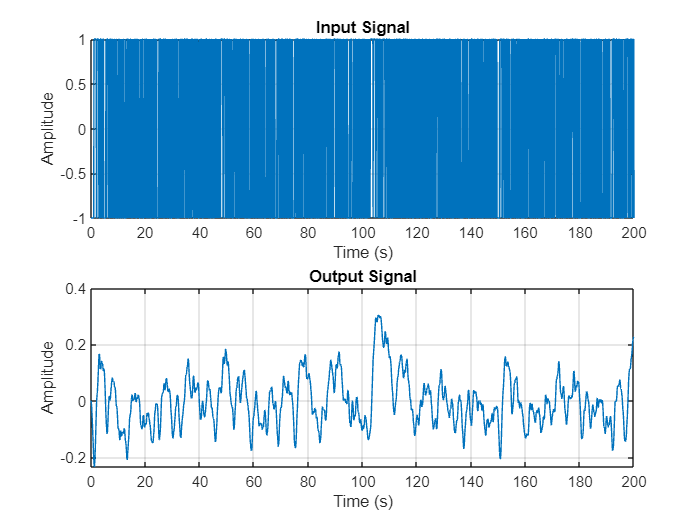

clear

warning off

%---------------------------------------------------------------
num = [1];
den = [1 3 2];
sys = tf(num, den);

Ts = 0.1; % Sample time for 10 Hz sample rate
Tfinal = 200;
t = 0:Ts:Tfinal;
u = idinput(length(t), 'prbs');
y = lsim(sys, u, t);
data= iddata(y,u,Ts);
figure;
subplot(2,1,1);
plot(t, u);
title('Input Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(2,1,2);
plot(t, y);
title('Output Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;



%---------------------------------------------------------------

## **b)**

- Calculate the autocorrelation of the output signal computed in “a-3” above with a maximum lag of 200. **Hint**: Use [**xcorr**](https://se.mathworks.com/help/matlab/ref/xcorr.html).

- Create a figure and plot the autocorrelation signal. **Hint:** You can use [**stem**](https://se.mathworks.com/help/matlab/ref/stem.html?s_tid=doc_ta) for plotting.

** (1 point)**

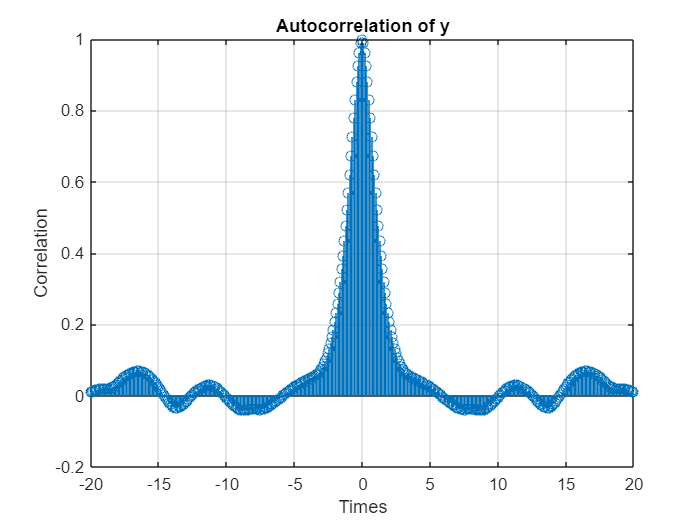

%---------------------------------------------------------------
[Ryy, lags] = xcorr(y, 200, 'coeff');
SampleTime=Ts;
figure;
stem(lags*SampleTime, Ryy, 'Marker','O');
title('Autocorrelation of y');
xlabel('Times');
ylabel('Correlation');
grid on;

%---------------------------------------------------------------

## **c)**

- Estimate the impulse response of the system using correlation analysis for 10 seconds. Create a figure and plot the estimated impulse response. **Hint**: Use [**cra**](https://se.mathworks.com/help/ident/ref/cra.html?s_tid=doc_ta).

- On the same figure, plot the actual simulated impulse response of the system, using the transfer function directly, for 10 seconds. **Hint:** Use [**impulse**](https://se.mathworks.com/help/ident/ref/dynamicsystem.impulse.html?s_tid=doc_ta).

** (2 points) **

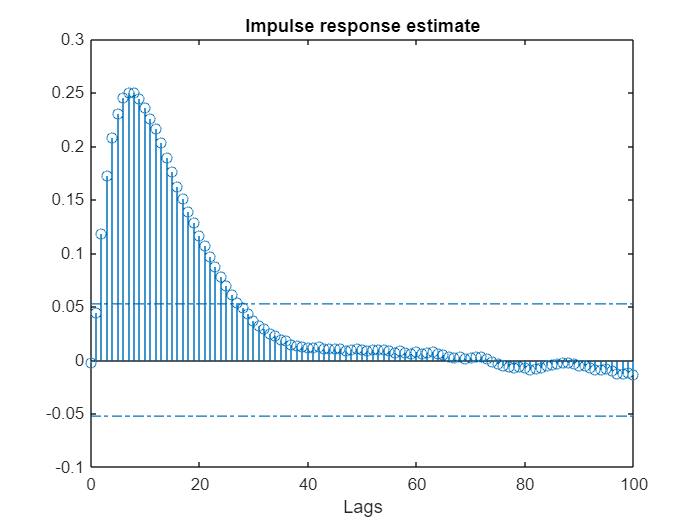

%---------------------------------------------------------------
M=100;
h_estimated = cra(u, y*10, M);

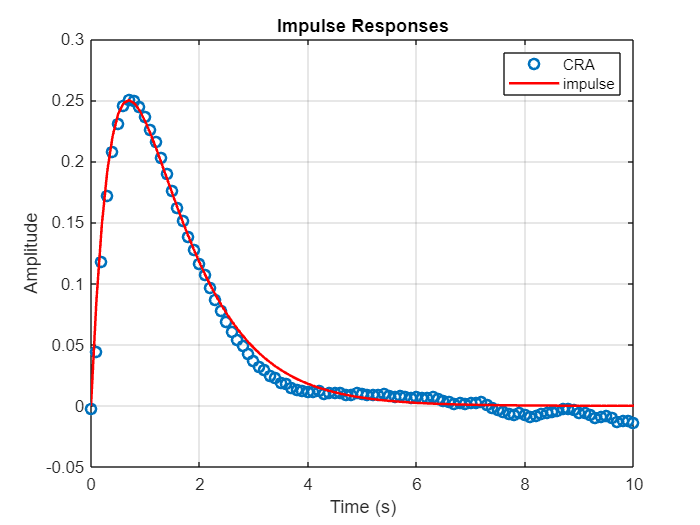

[h_actual, time] = impulse(sys, 0:Ts:10);
figure;
plot(time, h_estimated(1:length(time)), 'o', 'LineWidth', 1.5);
hold on;
plot(time, h_actual, 'r-', 'LineWidth', 1.5);
title('Impulse Responses');
xlabel('Time (s)');
ylabel('Amplitude');
legend('CRA', 'impulse');
grid on;
hold off;

%---------------------------------------------------------------

## **d)**

- Estimate the frequency response of the system using spectral analysis. **Hint: **Use [**spa**](https://se.mathworks.com/help/ident/ref/spa.html).

- Estimate the transfer function using the ETFE method. **Hint: **Use [**etfe**](https://se.mathworks.com/help/ident/ref/etfe.html?s_tid=doc_ta).

- Create a figure and display the Bode diagrams of both estimations on two subplots. **Hint: **Use [**bode**](https://se.mathworks.com/help/ident/ref/dynamicsystem.bode.html?s_tid=doc_ta).

** (1 point) **

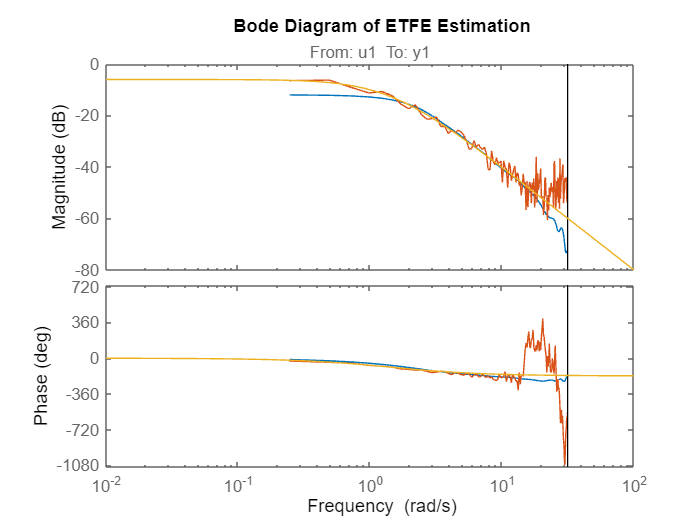

%---------------------------------------------------------------
G_spa = spa(data);
G_etfe = etfe(data);
bode(G_spa);
title('Bode Diagram of Spectral Analysis Estimation');
hold on;
bode(G_etfe);
bode(sys);
title('Bode Diagram of ETFE Estimation');
hold off;

%---------------------------------------------------------------

# **Problem 2 (5 points)**

- **The figure below shows the monthly USD prices of Bitcoin and Ethereum for the last three years (11.2020-10.2023). The related data are stored in the “data1.mat” datafile.**

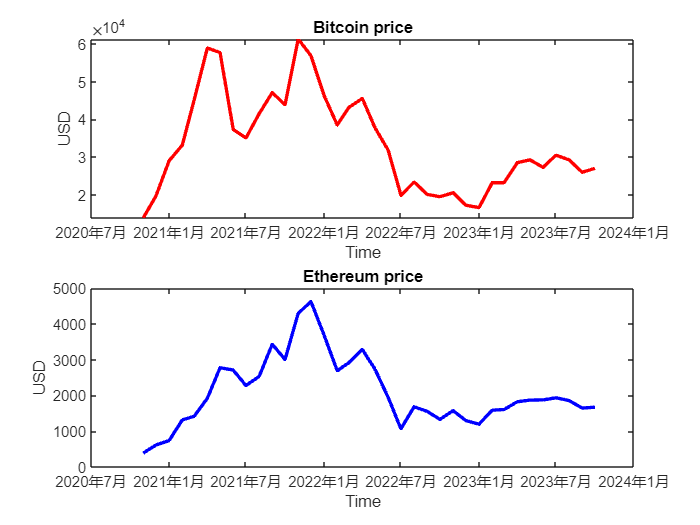

clear

load('data1.mat')

figure
subplot(2,1,1)
plot(time,bitcoin,'color','r','linewidth',2); ylabel('USD'); xlabel('Time'); title('Bitcoin price')
subplot(2,1,2)
plot(time,ethereum,'b','linewidth',2); ylabel('USD'); xlabel('Time'); title('Ethereum price')

## **a)**

- Analyze the quantitative relationship between the Bitcoin and Ethereum prices, i.e., determine whether they are correlated or not. Briefly explain the methodology behind your analysis and include the necessary calculations in the script below.

**(1.5 points) **

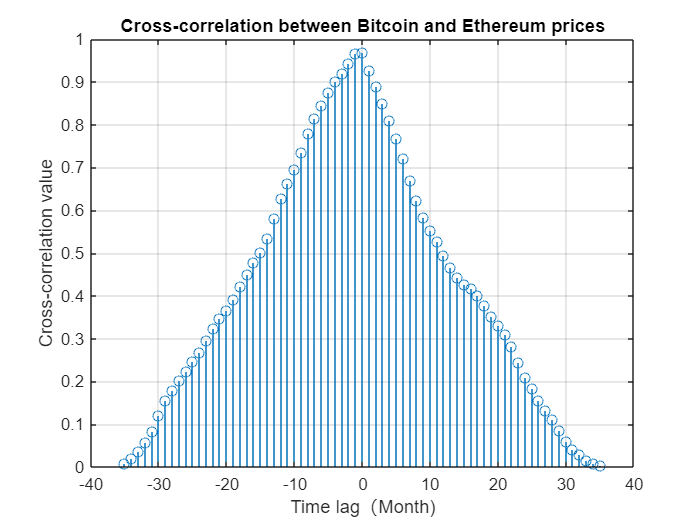

%---------------------------------------------------------------
% Compute Pearson correlation coefficient
[R, lags] = xcorr(bitcoin, ethereum, 'normalized');
% Plot the cross-correlation
figure;
stem(lags, R, 'Marker','o');
title('Cross-correlation between Bitcoin and Ethereum prices');
xlabel('Time lag（Month)');
ylabel('Cross-correlation value');
grid on;

% Analysis
[maxVal, maxIdx] = max(R);  % Find the maximum value and its index
peakLag = lags(maxIdx);  % Find the corresponding lag for the peak

fprintf('The peak of the cross-correlation occurs at a lag of %d months with a value of %.2f.\n', peakLag, maxVal);

The peak of the cross-correlation occurs at a lag of 0 months with a value of 0.97.


% I used xcorr to calculate the correlation as the calculation result of the xcorr can be interpreted as an estimate of the correlation between two random sequences, 
% or as a deterministic correlation between two deterministic signals.
% The peak of the cross-correlation occurs at a lag of 0 month with a value
% of 0.97,which means the Bitcoin and Ethereum prices have a strong positive linear relationship. 
% This means that, on average, when the price of Bitcoin increases, the price of Ethereum also tends to increase, and vice-versa.
%---------------------------------------------------------------

# Your Answer Below

## **b)**

- **Model selection:** Estimate a polynomial model to predict the Bitcoin price using the Ethereum price as an input. What polynomial order would you choose, and why? Provide your answer below. For estimation, you can use either MATLAB's Curve Fitting Toolbox or the [**polyfit**](https://se.mathworks.com/help/matlab/ref/polyfit.html) and [**polyval**](https://se.mathworks.com/help/matlab/ref/polyval.html) functions. If you decide to use Curve Fitting Toolbox, save the Toolbox-generated code in a separate script named "createFit.m" and call it from the script below to fit the chosen model. **Hint: **You can split the data into training and validation sets.

- **Visualize: **Make a [**scatter plot**](https://se.mathworks.com/help/matlab/ref/scatter.html) of the data (Bitcoin and Ethereum prices). On the same figure, plot the estimated function.

- **Predict **the Bitcoin price for the Ethereum price of 6000 USD.

**(3.5 points) **

%---------------------------------------------------------------
% Load data
clear
load('data1.mat')


% Split the data into training and validation sets
splitRatio = 0.75;
nData = length(bitcoin);
nTrain = floor(splitRatio * nData);

% Training data
train_ethereum = ethereum(1:nTrain);
train_bitcoin = bitcoin(1:nTrain);

% Validation data
valid_ethereum = ethereum(nTrain+1:end);
valid_bitcoin = bitcoin(nTrain+1:end);

% Polynomial orders to test
orders = 1:5;
SSEs = zeros(size(orders)); 

% Model training and evaluation
for i = 1:length(orders)
    p = polyfit(train_ethereum, train_bitcoin, orders(i));
    pred_bitcoin = polyval(p, valid_ethereum);
    SSEs(i) = sum((pred_bitcoin - valid_bitcoin).^2);  
end

% Model selection
[~, bestOrderIdx] = min(SSEs);  
bestOrder = orders(bestOrderIdx);
fprintf('Best polynomial order is: %d\n', bestOrder);

Best polynomial order is: 1


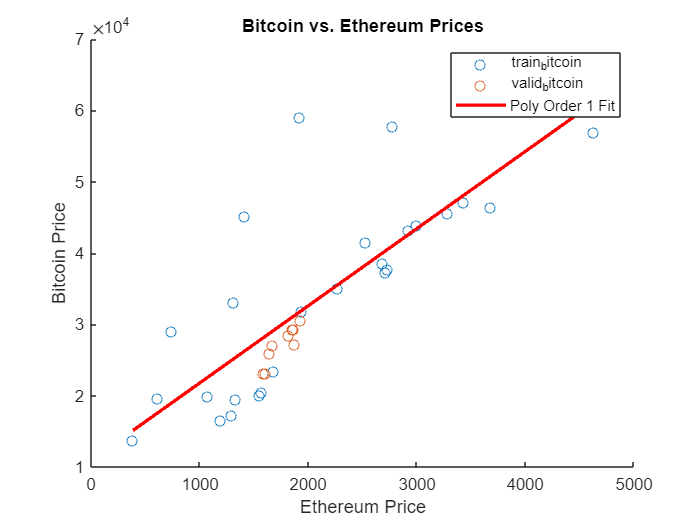

% Fit using the best polynomial order
p_best = polyfit(ethereum, bitcoin, bestOrder);

% Visualization
figure
scatter(train_ethereum, train_bitcoin, 'o')
hold on
scatter(valid_ethereum, valid_bitcoin, 'o')
eth_range = linspace(min(ethereum), max(ethereum), 100);
fit_bitcoin = polyval(p_best, eth_range);
plot(eth_range, fit_bitcoin, 'r', 'LineWidth', 2)
xlabel('Ethereum Price')
ylabel('Bitcoin Price')
legend('train_bitcoin','valid_bitcoin', sprintf('Poly Order %d Fit', bestOrder))
title('Bitcoin vs. Ethereum Prices')

% Predict the Bitcoin price for the Ethereum price of 6000 USD
predicted_bitcoin = polyval(p_best, 6000);
fprintf('Predicted Bitcoin price for Ethereum price of 6000 USD: %.2f\n', predicted_bitcoin);

Predicted Bitcoin price for Ethereum price of 6000 USD: 75901.70


# **What to return?**

You are expected to submit your assignment to the related link for Assignment 4 on MyCourses.

Your submission should include:

- One completed .mlx file: **Assignment_4_*your_student_number*.mlx**

- MATLAB script:** createFit.m **(optional)